# Geom-SINDy DSI vs SINDy DSI (consider ideal T&N space) - Set up at 2024May4

clear
clc

rng(1)

## Initialization

global n% ambient space dimension
global d% manifold dimension
global Xnoise
global Pnum
global index
global Dt

% Pnum=4000*2.5;%number of samples in training set
n=3;% ambient space dimension
d=2;% manifold dimension

## 1 Data set generation

#### Generate sample data set - Spring torus curve

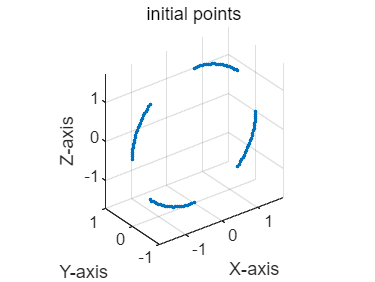

CycNum=1;%cycle number

t_total=20*2;
dt=1e-3;
t=0:dt:t_total;

I1=1.6;
I2=1;
I3=0.72;
PnumTol=size(t,2);

Cf=3/2;% take advantage of the energy radius of this Eular's equation of motion
r=sqrt(2*Cf);

curveNum = 200; % number of curves (must be multiple of 8)

% Generate evenly distributed points on the unit sphere
num_points = curveNum;
theta = 0;%绕z轴的角度（经度）
phi = linspace(0, 1*pi/4, num_points/4);%与z轴的夹角（纬度）
phi = [phi linspace(2*pi/4, 3*pi/4, num_points/4)];
phi = [phi linspace(4*pi/4, 5*pi/4, num_points/4)];
phi = [phi linspace(6*pi/4, 7*pi/4, num_points/4)];
x1 = r*sin(phi).*cos(theta);
x2 = r*sin(phi).*sin(theta);
x3 = r*cos(phi);

figure
plot3(x1,x2,x3,'.');title('initial points')
grid on;
axis equal; % Make sure the aspect ratio is the same for all axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

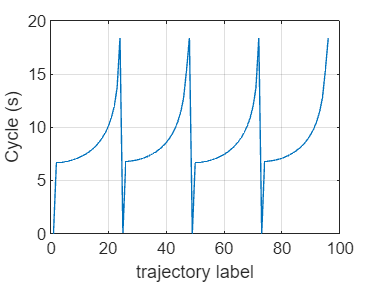


DataCloud = cell(1,curveNum); % preallocate cell array

for curN = 1:num_points
    X = zeros(n, PnumTol);
    X(:, 1) = [x1(curN); x2(curN); x3(curN)];
    
    for j = 1:PnumTol-1
        X1_hat = X(1, j) + dt*(1/I3-1/I2)*X(2, j)*X(3, j);
        X2_hat = X(2, j) + dt*(1/I1-1/I3)*X(1, j)*X(3, j);
        X3_hat = X(3, j) + dt*(1/I2-1/I1)*X(2, j)*X(1, j);
        X(1, j+1) = X(1, j) + dt*(1/I3-1/I2)*(X2_hat+X(2, j))/2*(X3_hat+X(3, j))/2;
        X(2, j+1) = X(2, j) + dt*(1/I1-1/I3)*(X1_hat+X(1, j))/2*(X3_hat+X(3, j))/2;
        X(3, j+1) = X(3, j) + dt*(1/I2-1/I1)*(X2_hat+X(2, j))/2*(X1_hat+X(1, j))/2;
        X(:,j+1)=X(:,j+1)/norm(X(:,j+1))*r;
    end
    
    DataCloud{curN} = X;
end

curvePointsPerCyc=[];
for curN=1:curveNum
    indices=[];
    queryPoint=DataCloud{curN}(:,1)';
    [indices, distances] = knnsearch(DataCloud{curN}', queryPoint, 'K', 10);
    indices(indices==1)=[];
    indices=sort(indices);
    if indices(1,2)/indices(1,1)>100
        curvePointsPerCyc(curN)=indices(1,2);
    else
        curvePointsPerCyc(curN)=indices(1,1);
    end
end
curvePointsPerCyc(1)=2;
curvePointsPerCyc(curveNum/4+1)=2;
curvePointsPerCyc(curveNum/2+1)=2;
curvePointsPerCyc(curveNum/4*3+1)=2;
Tcyc=(curvePointsPerCyc-1)*dt;

plot(Tcyc);
grid on
xlabel('trajectory label');ylabel('Cycle (s)')

% title('cycle of each trajectory')

#### Display

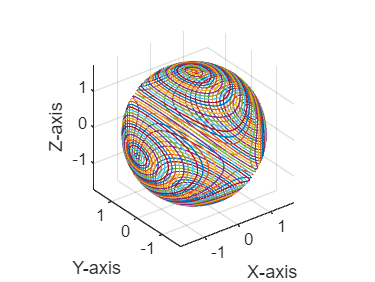

% Plot the manifold in 3D space
figure
for i=1:curveNum
plot3(DataCloud{i}(1,1:100:end), DataCloud{i}(2,1:100:end), DataCloud{i}(3,1:100:end));
hold on
end
hold off
grid on;
axis equal; % Make sure the aspect ratio is the same for all axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

% title('simulate data');

#### Sampling

part=1;

sp=50*20;% sampling muliple of simulation rate
Dt=sp*dt;

Pnum=round(CycNum*Tcyc/Dt+1);% curve points per cycle after sampling

Xnoise={};
Xsp={};
Xtrain={};
Xtest={};
Xsp_Together=[];
curN1=1;
curN2=1;
for curN=1:curveNum
    Xsp{curN}=zeros(n,Pnum(1,curN));
    for i=1:Pnum(1,curN)
        Xsp{curN}(:,i)=DataCloud{curN}(:,1+(i-1)*sp);% one cycle window length
    end
end

Xtrain=Xsp(1,1:2:end);curveNumTrain=size(Xtrain,2);
Xtest=Xsp(1,2:2:end);curveNumTest=size(Xtest,2);

for curN=1:curveNum
for i=1:floor(PnumTol/sp)
    Xsp_total{curN}(:,i)=DataCloud{curN}(:,1+(i-1)*sp);%full window length
end
end

Xtrain_total=Xsp_total(1,1:2:end);
Xtest_total=Xsp_total(1,2:2:end);

for curN=1:curveNum
Xsp_Together=[Xsp_Together Xsp{curN}];% knn search base
end

#### Display

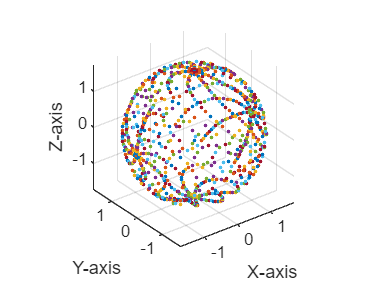

% Plot the manifold in 3D space
figure
for curN=1:curveNumTrain
plot3(Xtrain{curN}(1,:), Xtrain{curN}(2,:), Xtrain{curN}(3,:),'.');hold on
end
for curN=1:curveNumTest
plot3(Xtest{curN}(1,:), Xtest{curN}(2,:), Xtest{curN}(3,:),'.');hold on
end

grid on;hold off
axis equal; % Make sure the aspect ratio is the same for all axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

## 2 SINDy model building

Prepare the tangent and normal space for training

Pn=sum(Pnum);
knear=round(Pn^0.5);

Tbox={};Ttrain={};
Nbox={};Ntrain={};

for curN=1:curveNum
    for i=1:Pnum(1,curN)
        [Tbox{curN,i},Nbox{curN,i}]=TNspace_EulerSphere_Ideal(Xsp{curN}(:,i));
    end
end
count=0;
for curN=1:curveNumTrain
Ttrain{curN}=Tbox(1+count,:);
Ntrain{curN}=Nbox(1+count,:);
count=count+2;
end
count=0;
for curN=1:curveNumTest
Ttest{curN}=Tbox(2+count,:);
Ntest{curN}=Nbox(2+count,:);
count=count+2;
end

Solve the GeoSINDy model

Numtrain=sum(Pnum(1:2:end));% number of points in training set
Klib=1+3*n;% number of candidate function
dotX_trainMatrix=zeros(Numtrain,n);
library_trainMatrix=[];

dotXtrain={};dotXtrain_T_amb={};
for curN=1:curveNumTrain
if curN==0+1||curN==curveNumTrain/4+1||curN==curveNumTrain/2+1||curN==curveNumTrain/4*3+1
    dotXtrain{curN}=zeros(n,1);
else
    PreStepMatrix=Xtrain{curN};
    NextStepMatrix=Xtrain{curN};
    PreStepMatrix(:,end)=[];
    NextStepMatrix(:,1)=[];
    dotXtrain{curN}=(NextStepMatrix-PreStepMatrix)/Dt;

    flag=ones(size(Pnum(1,1:2:end)));flag(1,1)=0;flag(1,curveNumTrain/4+1)=0;flag(1,curveNumTrain/2+1)=0;flag(1,curveNumTrain/4*3+1)=0;
    flagf=Pnum(1,1:2:end)-flag;
    for i=1:flagf(1,curN)
        T=Ttrain{curN};
        dotXtrain_T_amb{curN}(:,i)=T{i}*T{i}'*dotXtrain{curN}(:,i);
    end
end
end

dotXtrain_T_amb{1}=zeros(n,1);
dotXtrain_T_amb{curveNumTrain/4+1}=zeros(n,1);
dotXtrain_T_amb{curveNumTrain/2+1}=zeros(n,1);
dotXtrain_T_amb{curveNumTrain/4*3+1}=zeros(n,1);

dotXtrainTambMatrix=[];
for i=1:curveNumTrain
    dotXtrainTambMatrix=[dotXtrainTambMatrix dotXtrain_T_amb{i}];
end
dotXtrainTambMatrix=dotXtrainTambMatrix';

XtrainMatrix=[];
for curN=1:curveNumTrain
    if curN==0+1||curN==curveNumTrain/4+1||curN==curveNumTrain/2+1||curN==curveNumTrain/4*3+1
        XtrainMatrix=[XtrainMatrix Xtrain{curN}];
    else
        XtrainMatrix=[XtrainMatrix Xtrain{curN}(:,1:end-1)];
    end
end
for i=1:size(XtrainMatrix,2)
    library_trainMatrix(i,:)=CandidateFunVector(XtrainMatrix(:,i));
end


lambda=1e-4;
Coef_IdlGeomSINDy = sparsifyDynamics(library_trainMatrix,dotXtrainTambMatrix,lambda,n)

Coef_IdlGeomSINDy =          0         0         0
    0.0377         0   -0.0008
         0   -0.1175         0
   -0.0015         0    0.0415
         0   -0.0004         0
         0    0.0001         0
         0         0         0
   -0.0006         0    0.3537
    0.3640         0   -0.0009
         0   -0.6802         0


Solve the SINDy model

Ntrain=sum(Pnum(1:2:end));% number of points in training set
Klib=1+3*n;% number of candidate function
dotX_trainMatrix=zeros(Ntrain,n);

dotXtrainMatrix=[];
for i=1:curveNumTrain
    dotXtrainMatrix=[dotXtrainMatrix dotXtrain{i}];
end
dotXtrainMatrix=dotXtrainMatrix';

lambda=1e-4;
Coef_IdlSINDy = sparsifyDynamics(library_trainMatrix,dotXtrainMatrix,lambda,n)

Coef_IdlSINDy =          0         0         0
   -0.0330         0   -0.0020
         0   -0.1850         0
   -0.0027         0   -0.0307
         0   -0.0007         0
         0    0.0003         0
         0   -0.0002         0
   -0.0024         0    0.3352
    0.3454         0   -0.0024
         0   -0.6983         0


## 3 Prediction 

#### Purely prediction without correction algorithm in each step

Predict a trajectory traveling on the manifold **only given the initial points**.

GeoSINDy model:

Xpre={};
error_GeoSINDy={};

for curN=1:curveNumTest
Xpre{curN}=zeros(size(Xtest{curN}));
Xpre{curN}(:,1)=Xtest{curN}(:,1);%+0.002*randn(size(X(:,1:1+shiftStr)));

%=====mode selecting========
% nodes=size(Xtest{curN},2);% one cycle for each curve
nodes=size(Xtest{curveNumTest},2);% The same time length for all curve (at leaset 1 cycle of the biggest curve)
%================

degr=3;% GMLS parameter

error_GeoSINDy{curN}=zeros(1,nodes+1);

for i=1:nodes
    % case1=================Calculate Ti and Ni===================
    % queryPoint=Xpre{curN}(:,i)';
    % [indices, distances] = knnsearch(Xsp_Together', queryPoint, 'K', knear);
    % DistPoint=Xsp_Together(:,indices);
    % Dist=DistPoint-queryPoint';
    % [U,S,Vt]=svd(Dist);
    % U=SVD_U_SignAlignment(U);
    % Ti=U(:,1:d);%n*d
    % Ni=U(:,d+1:n);%n*(n-d)
    % 
    % Tisee{i}=Ti;
    % Nisee{i}=Ni;
    % 
    % xi=Xpre{curN}(:,i);
    % dXTambpDt=(CandidateFunVector(xi)*Coef_IdlGeomSINDy)';
    % dXTamb=dXTambpDt*Dt;
    % dXNamb=GMLS_for_VerticalInc(Dist,Ti,Ni,dXTamb)
    % =====================================
    
    % case2=========use ideal way to obtain Ti and Ni============
    xi=Xpre{curN}(:,i);
    [Ti,Ni]=TNspace_EulerSphere_Ideal(xi);

    dXTambpDt=(CandidateFunVector(xi)*Coef_IdlGeomSINDy)';
    dXpDt=dXTambpDt;
    dXTamb=dXTambpDt*Dt;
    queryPoint=xi';

    [indices, distances] = knnsearch(Xsp_Together', queryPoint, 'K', knear);
    DistPoint=Xsp_Together(:,indices);
    Dist=DistPoint-queryPoint';
    dXNamb=GMLS_for_VerticalInc(Dist,Ti,Ni,dXTamb,degr,knear,d);% here we still must use GMLS since we cannot determine ideal normal increment as we cannot get xi+1 ideally (if so the test will become meanless and always zero error)
    % =========================================================

    % case3===========use ideal way to obtain Ti and Ni and vertical increment (this offline method very bad)==========
    % xi=Xpre{curN}(:,i);
    % [Ti,Ni]=TNspace_EulerSphere_Ideal(xi);
    % dXTambpDt=(CandidateFunVector(xi)*Coef_IdlGeomSINDy)';
    % dXTamb=dXTambpDt*Dt;
    % dXNamb=Ni*Ni'*(Xtest_total{curN}(:,i+1)-xi);
    % ==============================

    Xpre{curN}(:,i+1)=Xpre{curN}(:,i)+dXTamb+dXNamb;
  
    error_GeoSINDy{curN}(i+1)=norm(Xpre{curN}(:,i+1)-Xtest_total{curN}(:,i+1))/r;
    errorOffManifold_GeoSINDy{curN}(i+1)=abs(norm(Xpre{curN}(:,i+1))-r)/r;
end
e=max(error_GeoSINDy{curN})
eOffMan=max(errorOffManifold_GeoSINDy{curN})

fig=0;
if fig==1
    curN
figure
plot3(Xpre{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(2,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(3,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1),'.','Linewidth', 0.1);title('prediction performance')
hold on
plot3(Xtest_total{curN}(1,1:nodes), Xtest_total{curN}(2,1:nodes), Xtest_total{curN}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
figure
plot3(Xpre{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(2,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(3,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1));title('prediction performance')
figure
plot(error_GeoSINDy{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1));title('relative error for each step')
end

end

e = 1.0134

eOffMan = 0.0975

e = 1.1630

eOffMan = 0.0966

e = 1.2821

eOffMan = 0.0915

e = 1.3777

eOffMan = 0.0951

e = 1.4314

eOffMan = 0.0981

e = 1.4805

eOffMan = 0.0999

e = 1.5361

eOffMan = 0.1010

e = 1.5934

eOffMan = 0.1017

e = 1.6791

eOffMan = 0.1021

e = 1.7549

eOffMan = 0.0997

e = 1.7563

eOffMan = 0.1017

e = 1.4449

eOffMan = 0.1034

e = 0.9923

eOffMan = 0.0699

e = 1.1615

eOffMan = 0.0987

e = 1.2972

eOffMan = 0.0920

e = 1.3748

eOffMan = 0.0969

e = 1.4549

eOffMan = 0.0991

e = 1.4704

eOffMan = 0.1012

e = 1.5077

eOffMan = 0.1024

e = 1.5880

eOffMan = 0.1028

e = 1.6767

eOffMan = 0.0998

e = 1.7667

eOffMan = 0.1020

e = 1.8433

eOffMan = 0.1041

e = 1.4434

eOffMan = 0.1034

e = 1.0134

eOffMan = 0.0975

e = 1.1630

eOffMan = 0.0966

e = 1.2821

eOffMan = 0.0915

e = 1.3777

eOffMan = 0.0951

e = 1.4314

eOffMan = 0.0981

e = 1.4805

eOffMan = 0.0999

e = 1.5361

eOffMan = 0.1010

e = 1.5934

eOffMan = 0.1017

e = 1.6791

eOffMan = 0.1021

e = 1.7549

eOffMan = 0.0997

e = 1.7563

eOffMan = 0.1017

e = 1.4449

eOffMan = 0.1034

e = 0.9923

eOffMan = 0.0699

e = 1.1615

eOffMan = 0.0987

e = 1.2972

eOffMan = 0.0920

e = 1.3748

eOffMan = 0.0969

e = 1.4549

eOffMan = 0.0991

e = 1.4704

eOffMan = 0.1012

e = 1.5077

eOffMan = 0.1024

e = 1.5880

eOffMan = 0.1028

e = 1.6767

eOffMan = 0.0998

e = 1.7667

eOffMan = 0.1020

e = 1.8433

eOffMan = 0.1041

e = 1.4434

eOffMan = 0.1034

SINDy model:

Xpre={};
errorOnly_SINDy={};

for curN=1:curveNumTest
Xpre{curN}=zeros(size(Xtest{curN}));
Xpre{curN}(:,1)=Xtest{curN}(:,1);%+0.002*randn(size(X(:,1:1+shiftStr)));

%=====mode selecting========
% nodes=size(Xtest{curN},2);% one cycle for each curve
nodes=size(Xtest{curveNumTest},2);% The same time length for all curve (at leaset 1 cycle of the biggest curve)
%================

errorOnly_SINDy{curN}=zeros(1,nodes+1);

for i=1:nodes%Pnum-1
    xi=Xpre{curN}(:,i);
    dXpDt=(CandidateFunVector(xi)*Coef_IdlSINDy)';
    Xpre{curN}(:,i+1)=Xpre{curN}(:,i)+dXpDt*Dt;
  
    errorOnly_SINDy{curN}(i+1)=norm(Xpre{curN}(:,i+1)-Xtest_total{curN}(:,i+1))/r;
    errorOffManifoldOnly_SINDy{curN}(i+1)=abs(norm(Xpre{curN}(:,i+1))-r)/r;
end

e=max(errorOnly_SINDy{curN});
eOffMan=max(errorOffManifoldOnly_SINDy{curN});

fig=0;
if fig==1
    curN
figure
plot3(Xpre{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(2,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(3,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1),'.','Linewidth', 0.1);title('prediction performance')
hold on
plot3(Xtest_total{curN}(1,1:nodes), Xtest_total{curN}(2,1:nodes), Xtest_total{curN}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
figure
plot3(Xpre{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(2,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1), Xpre{curN}(3,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1));title('prediction performance')
figure
plot(errorOnly_SINDy{curN}(1,1+shiftStr(sh,1):nodes+shiftStr(sh,1)+1));title('relative error for each step')
end

end

e = 0.5300

eOffMan = 0.4219

e = 0.9137

eOffMan = 0.3011

e = 1.3738

eOffMan = 0.1550

e = 1.7163

eOffMan = 0.3212

e = 1.8446

eOffMan = 0.4407

e = 1.9218

eOffMan = 0.5401

e = 1.7542

eOffMan = 0.5590

e = 1.5445

eOffMan = 0.5472

e = 1.5286

eOffMan = 0.5337

e = 1.4536

eOffMan = 0.7009

e = 1.3314

eOffMan = 0.8366

e = 1.0757

eOffMan = 0.8103

e = 0.5284

eOffMan = 0.4533

e = 0.8722

eOffMan = 0.3356

e = 1.2805

eOffMan = 0.2521

e = 1.5331

eOffMan = 0.3425

e = 1.7197

eOffMan = 0.5311

e = 1.6404

eOffMan = 0.5899

e = 1.5054

eOffMan = 0.5732

e = 1.5323

eOffMan = 0.5403

e = 1.5065

eOffMan = 0.6146

e = 1.4301

eOffMan = 0.8196

e = 1.2853

eOffMan = 0.8361

e = 1.0998

eOffMan = 0.8376

e = 0.5300

eOffMan = 0.4219

e = 0.9137

eOffMan = 0.3011

e = 1.3738

eOffMan = 0.1550

e = 1.7163

eOffMan = 0.3212

e = 1.8446

eOffMan = 0.4407

e = 1.9218

eOffMan = 0.5401

e = 1.7542

eOffMan = 0.5590

e = 1.5445

eOffMan = 0.5472

e = 1.5286

eOffMan = 0.5337

e = 1.4536

eOffMan = 0.7009

e = 1.3314

eOffMan = 0.8366

e = 1.0757

eOffMan = 0.8103

e = 0.5284

eOffMan = 0.4533

e = 0.8722

eOffMan = 0.3356

e = 1.2805

eOffMan = 0.2521

e = 1.5331

eOffMan = 0.3425

e = 1.7197

eOffMan = 0.5311

e = 1.6404

eOffMan = 0.5899

e = 1.5054

eOffMan = 0.5732

e = 1.5323

eOffMan = 0.5403

e = 1.5065

eOffMan = 0.6146

e = 1.4301

eOffMan = 0.8196

e = 1.2853

eOffMan = 0.8361

e = 1.0998

eOffMan = 0.8376

## 4 Performance comparing

off manifold error

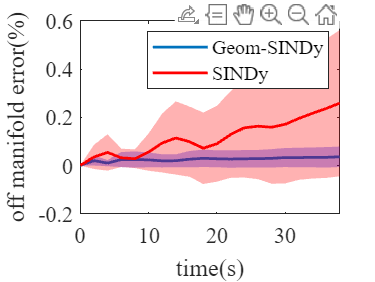

errorTN_SINDy1=errorOffManifold_GeoSINDy;

errorOnly_SINDy1=errorOffManifoldOnly_SINDy;


X_ErrorMatrix=zeros(curveNum,size(errorTN_SINDy1{1},2));

for curN=1:curveNumTest
X_ErrorMatrix(curN,:)=errorTN_SINDy1{curN};
end

steps=1:1:size(errorTN_SINDy1{curN},2);
X_AveError=mean(X_ErrorMatrix);

X_ErrorMatrixOnlySINDy=zeros(curveNum,size(errorOnly_SINDy1{1},2));

for curN=1:curveNumTest
X_ErrorMatrixOnlySINDy(curN,:)=errorOnly_SINDy1{curN};
end

steps=1:1:size(errorOnly_SINDy1{curN},2);
time=(steps-1)*2*Dt;

X_AveErrorOnlySINDy=mean(X_ErrorMatrixOnlySINDy);
frontsize=12;

figure%relative error sample 
f_upper=X_AveError+std(X_ErrorMatrix);f_lower=X_AveError-std(X_ErrorMatrix);
plot(time,X_AveError, 'LineWidth', 1.5);hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveErrorOnlySINDy+std(X_ErrorMatrixOnlySINDy);f_lower=X_AveErrorOnlySINDy-std(X_ErrorMatrixOnlySINDy);
plot(time,X_AveErrorOnlySINDy, 'LineWidth', 1.5,'Color','r');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold off;

xlabel('time(s)');ylabel('off manifold error(%)');legend('Geom-SINDy','','SINDy')
set(gca, 'FontName', 'Times New Roman', 'FontSize', frontsize);xlim([0,time(end)])

% set(gca, 'YScale', 'log')

norm2 error

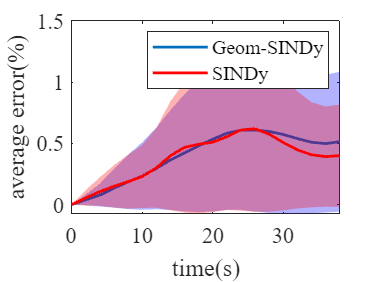

errorTN_SINDy2=error_GeoSINDy;

errorOnly_SINDy2=errorOnly_SINDy;


X_ErrorMatrix=zeros(curveNum,size(errorTN_SINDy2{1},2));

for curN=1:curveNumTest
X_ErrorMatrix(curN,:)=errorTN_SINDy2{curN};
end

steps=1:1:size(errorTN_SINDy2{curN},2);
X_AveError=mean(X_ErrorMatrix);

X_ErrorMatrixOnlySINDy=zeros(curveNum,size(errorOnly_SINDy2{1},2));

for curN=1:curveNumTest
X_ErrorMatrixOnlySINDy(curN,:)=errorOnly_SINDy2{curN};
end

steps=1:1:size(errorOnly_SINDy2{curN},2);
time=(steps-1)*2*Dt;

X_AveErrorOnlySINDy=mean(X_ErrorMatrixOnlySINDy);
frontsize=12;

figure%relative error sample 
f_upper=X_AveError+std(X_ErrorMatrix);f_lower=X_AveError-std(X_ErrorMatrix);
plot(time,X_AveError, 'LineWidth', 1.5);hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveErrorOnlySINDy+std(X_ErrorMatrixOnlySINDy);f_lower=X_AveErrorOnlySINDy-std(X_ErrorMatrixOnlySINDy);
plot(time,X_AveErrorOnlySINDy, 'LineWidth', 1.5,'Color','r');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold off;

xlabel('time(s)');ylabel('average error(%)');legend('Geom-SINDy','','SINDy')
set(gca, 'FontName', 'Times New Roman', 'FontSize', frontsize);xlim([0,time(end)])